## Problem 2

clear;
rng(0);

Consider two independent Poisson random variables $X$ and $Y$ , with parameters $\lambda_X := 3$ and $\lambda_Y := 4$. 

lmd_x=3;    %value of the average of X
lmd_y=4;    %value of the average of Y

- Define a random variable $Z := X + Y$ , having a probability mass function (PMF) $P(Z)$. 

 (i) Empirically obtain an estimate $\hat{P}(Z)$ of the PMF $P(Z)$, by drawing $N = 10^6$ instances (sample points) of $X$ and $Y$ both. You may use the poissrnd(.) function in Matlab. Report the values of $\hat{P}(Z = k)$ for $k = 0, 1, 2, \cdots , 25$. 

N=10^6;     %number of draws
% Z = X + Y we do for all instances together
Z_1 = poissrnd(lmd_x, N, 1)+poissrnd(lmd_y, N, 1)

Z_1 =     10
    11
     5
     7
    11
     3
    10
     8
     8
     9


P_emp_1 = hist(Z_1,(0:25));  %store the occurences of 0-25 numbers, empirical estimate PMF
P_emp_1 = P_emp_1 / sum(P_emp_1)    %find the probability of 0-25

P_emp_1 =     0.0009    0.0064    0.0224    0.0524    0.0913    0.1274    0.1488    0.1489    0.1304    0.1013    0.0710    0.0451    0.0264    0.0143    0.0072    0.0033    0.0015    0.0006    0.0002    0.0001    0.0000    0.0000    0.0000         0         0         0


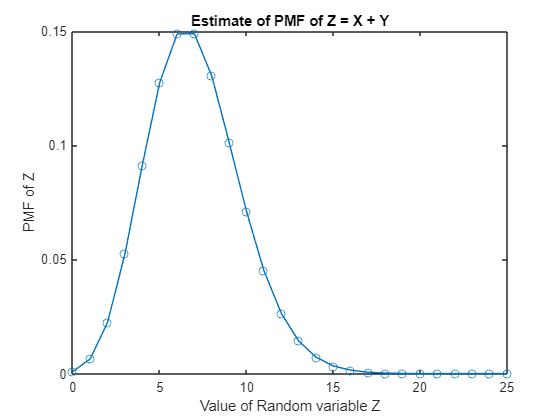

plot((0:25),P_emp_1,'-o'), xlabel("Value of Random variable Z"), ylabel("PMF of Z"), title("Estimate of PMF of Z = X + Y")   %plot the graph of PMF from 0-25

(ii) What will the PMF $P(Z)$ be theoretically/analytically ? 

The poisson distribution is


$$P_\lambda(a) = \frac{\lambda^a}{a!} e^{-\lambda}$$


$P(Z=z)$ is


$$P(Z=z) = \sum_{x=0}^z P(X=x)\cdot P(Y=z-x)$$



$$= \sum_{x=0}^z \frac{\lambda_x^x}{x!}\frac{\lambda_y^{z-x}}{(z-x)!} e^{-\lambda_x -\lambda_y}$$



$$= \sum_{x=0}^z \frac{(\lambda_x/\lambda_y)^x \cdot{ }^zC_x}{z! } \lambda_y^z e^{-\lambda_x -\lambda_y}$$



$$= \frac{(\lambda_x+\lambda_y)^z}{z!} e^{-(\lambda_x+\lambda_y)}$$


This is a new poisson distribution.

(iii) Show and compare the values for $\hat{P}(Z = k)$ and $P(Z = k)$ for $k = 0, 1, 2, \cdots , 25$.

P_th_1 = (lmd_x+lmd_y).^(0:25) * exp(-lmd_x-lmd_y) ./factorial(0:25);    %Theoretical values of PMF of Z
disp([(0:25);P_th_1;P_emp_1]);   %display the theoretical PMF & estimated PMF of Z

  Columns 1 through 10

         0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0009    0.0064    0.0223    0.0521    0.0912    0.1277    0.1490    0.1490    0.1304    0.1014
    0.0009    0.0064    0.0224    0.0524    0.0913    0.1274    0.1488    0.1489    0.1304    0.1013

  Columns 11 through 20

   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000
    0.0710    0.0452    0.0263    0.0142    0.0071    0.0033    0.0014    0.0006    0.0002    0.0001
    0.0710    0.0451    0.0264    0.0143    0.0072    0.0033    0.0015    0.0006    0.0002    0.0001

  Columns 21 through 26

   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000         0         0         0



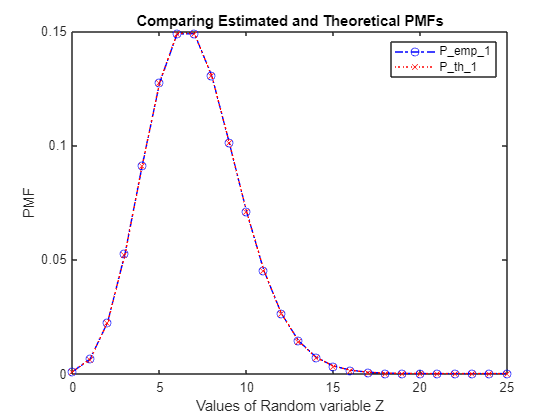

plot((0:25),P_emp_1,'b-.o'), xlabel("Values of Random variable Z"), ylabel("PMF"), title("Comparing Estimated and Theoretical PMFs");  % Plot the Empirical PMF
hold on;
plot((0:25),P_th_1,'r:x');   % Plot the theoretical PMF
legend('P\_emp\_1', 'P\_th\_1');
hold off;

- Implement a Poisson thinning process (as discussed in class) on the random variable Y , where the thinning process uses probability parameter 0.8. Let the thinned random variable be Z.  

(i) Empirically obtain an estimate $\hat{P}(Z)$ of the PMF $P(Z)$, by drawing $N := 10^5$ instances (sample points) from $Y$ . You may use the poissrnd(.) and binornd(.) functions in Matlab. Report the values of $\hat{P}(Z = k)$ for $k = 0, 1, 2, \cdots , 25$. 

N=10^5;   % number of instances
p=0.8;    % thinning probability
Y_2= poissrnd(lmd_y,N,1)    % An intermediate poisson random variable used to calculate the thinned variable

Y_2 =      2
     4
     6
     6
     3
     5
     1
     8
     1
     4


Z_2=binornd(Y_2,p)     % replace the intermediate poisson random variable with a binomial distribution applied over the random variable with parameter p=0.8

Z_2 =      2
     2
     5
     3
     2
     4
     1
     4
     0
     3


P_emp_2 = hist(Z_2,(0:25));   
P_emp_2 = P_emp_2 /sum(P_emp_2)     % Empirical PMF for thinning (0-25)   

P_emp_2 =     0.0415    0.1299    0.2078    0.2247    0.1784    0.1134    0.0612    0.0268    0.0106    0.0038    0.0012    0.0004    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0


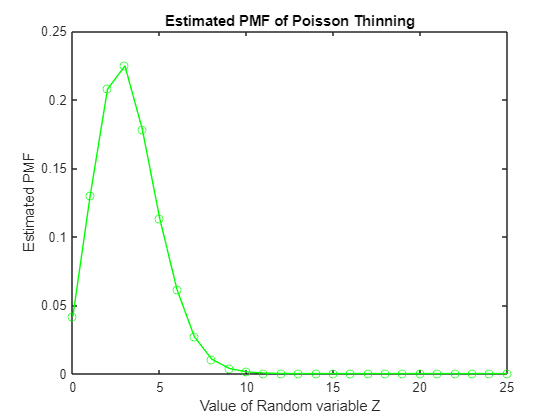

plot((0:25),P_emp_2,'g-o'), xlabel("Value of Random variable Z"), ylabel("Estimated PMF"), title("Estimated PMF of Poisson Thinning");   % Plot of estimated PMF of poisson thinning

(ii) What will the PMF $P(Z)$ be theoretically/analytically ? 

refer slides and fill here


$$= \frac{e^{-\lambda p}(\lambda p)^k}{k!}$$


(iii) Show and compare the values for $\hat{P}(Z = k)$ and $P(Z = k)$ for $k = 0, 1, 2, \cdots , 25$.

P_th_2 = (lmd_y*p).^(0:25) * exp(-lmd_y*p) ./factorial(0:25);    % Theoretical PMF of poisson thinning

disp([(0:25); P_th_2; P_emp_2]);

  Columns 1 through 10

         0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0408    0.1304    0.2087    0.2226    0.1781    0.1140    0.0608    0.0278    0.0111    0.0040
    0.0415    0.1299    0.2078    0.2247    0.1784    0.1134    0.0612    0.0268    0.0106    0.0038

  Columns 11 through 20

   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000
    0.0013    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0012    0.0004    0.0001    0.0000    0.0000         0         0         0         0         0

  Columns 21 through 26

   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0



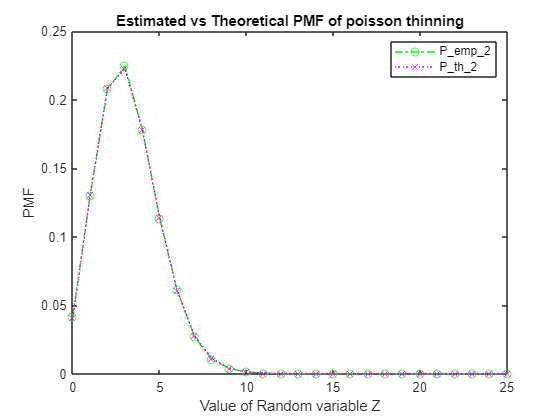

plot((0:25),P_emp_2,'g-.o'), xlabel("Value of Random variable Z"), ylabel("PMF"), title("Estimated vs Theoretical PMF of poisson thinning");   % Plot of estimated PMF of poisson thinning;
hold on;
plot((0:25),P_th_2,'m:x');   % Plot the theoretical PMF of poisson thinning
legend('P\_emp\_2', 'P\_th\_2');
hold off;